# **ACM 11 Homework 5 Part 1/2 **

# **(Spring 2024)**

## **Due Friday, June 7th, 11:59pm Pacific Time, by upload to Canvas.**

This assignment is composed of two parts. This first part is worth $40$ points. You should read the problem set-up in this file and follow the instructions to write and test your code. 

## Introduction

In this problem, we will use a auto data set from Tibshirani's *Introduction to Statistical Learning *to predict automobile performance, or to be more specific, whether a car will have high or low gas mileage. The data set, named as Auto, has 8 characteristics of 392 different vehicles: mpg, cylinders, displacement, horsepower, weight, acceleration, year and origin (1=American, 2 = European, 3 = Japanese). This file, Part 1, familiarizes you with the data set and asks you to fit a model using linear regression. In Part 2, you will consider regularization approaches for model fitting using this dataset.

## Problem 1: Load and explore the data set (20 points)

**(1a) (2 points) **Please load the ''Auto.csv" data set into matlab. Notice that the data set contains numbers and also strings (you may open the csv file to check first). The `READTABLE` function in MATLAB will be useful here. Note that `READTABLE` outputs a struct where each variable is a field of the struct. To access one of these fields, use the syntax `struct_name.field_name`.

clear; close all
struct = readtable('Auto.csv');

**(1b) (8 points)** We will consider the first 7 variables in the dataset: mpg, cylinders, displacement, horsepower, weight, acceleration, and year. To visualize these numerical variables, we will use the MATLAB function `PLOTMATRIX`. To use this function, you will have to create a matrix where each column corresponds to one of these variables. Hint: the MATLAB function TABLE2ARRAY may be useful. Calling `PLOTMATRIX` on this matrix will yield a plot with a 7x7 grid of subplots. The diagonal of this grid contains histograms of the values in the data set for each variable. The (i,j) off-diagonal plot displays a scatterplot of the values of the i-th variable vs. the j-th variable in your matrix. Label the x-axes of the bottom-most plots and the y-axes of the left-most plots with the variable names. Hint: [see this MATLAB Answer on how to add labels](https://www.mathworks.com/matlabcentral/answers/183203-add-label-to-sub-axes-in-plotmatrix#answer_282775).

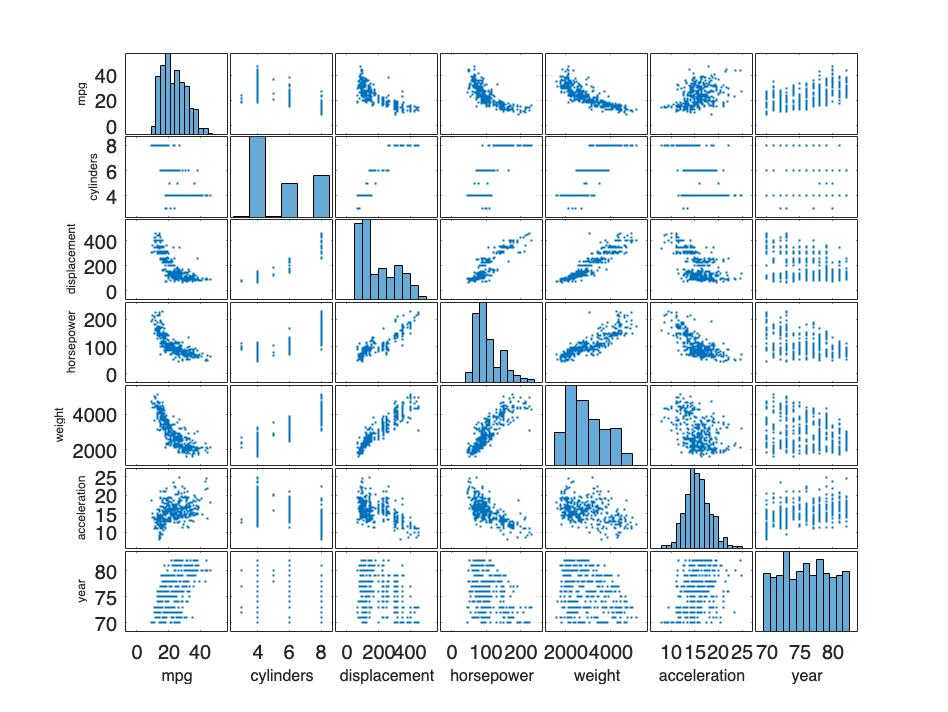

names = {'mpg', 'cylinders', 'displacement', 'horsepower','weight', 'acceleration', 'year'};
mat = table2array(table(struct.mpg, struct.cylinders, struct.displacement, ...
                struct.horsepower, struct.weight, struct.acceleration, struct.year) ...
                ,'VariableNames',names);
[~, ax] = plotmatrix(mat);
iterations = size(ax,1);
for i = 1:iterations
    ax(i,1).YLabel.String = names(i);
    ax(i, 1).YLabel.FontSize = 6;
    ax(iterations,i).XLabel.String = names(i);
    ax(iterations, i).XLabel.FontSize = 8;
end

**(1c) (4 points) **From your plot in (1b), focus on the MPG column/row. Do any variables stand out has having positive correlation with MPG (ie if the variable goes up, MPG also goes up)? Negative correlation (if the variable goes down, MPG goes up)? No strong correlation?

fprintf(['Based on the plot from 1b, it seems that there is a slight positive correlation between mpg and year.\n' ...
    'There seems to be a slightly negative correlation between mpg and cylinders, displacement, horsepower, and weight. \n' ...
    'There is no strong correlation between mpg and acceleration.'])

Based on the plot from 1b, it seems that there is a slight positive correlation between mpg and year.
There seems to be a slightly negative correlation between mpg and cylinders, displacement, horsepower, and weight. 
There is no strong correlation between mpg and acceleration.

**(1d) (6 points) **In (1c) we asked you to assess correlation by visual inspection of scatter plots. Now, we will compute correlation numerically using MATLAB's `CORR` function. Call `CORR` on the same matrix you called `PLOTMATRIX` on before. The result will be a 7x7 matrix containing values of correlation coefficients between the variables. You will see that the diagonal is made up of 1's - because a variable is by definition perfectly correlated with itself. 

corr(mat)

ans =     1.0000   -0.7776   -0.8051   -0.7784   -0.8322    0.4233    0.5805
   -0.7776    1.0000    0.9508    0.8430    0.8975   -0.5047   -0.3456
   -0.8051    0.9508    1.0000    0.8973    0.9330   -0.5438   -0.3699
   -0.7784    0.8430    0.8973    1.0000    0.8645   -0.6892   -0.4164
   -0.8322    0.8975    0.9330    0.8645    1.0000   -0.4168   -0.3091
    0.4233   -0.5047   -0.5438   -0.6892   -0.4168    1.0000    0.2903
    0.5805   -0.3456   -0.3699   -0.4164   -0.3091    0.2903    1.0000


Look at the row/column associated with MPG. Larger positive values mean stronger positive correlation with MPG; more negative values mean stronger negative correlation. Do these computed correlation coefficients match your observations above? Which variable has the strongest correlation (positive or negative) with MPG (ie largest absolute value of correlation coefficient, not including MPG itself)? Are any of your predictions to have no strong correlation suprising?

fprintf(['The correlation coefficients from part 1d pretty much match my predicitons in 1c. There is the strongest negative \n' ...
    'correlation between mpg and weight, while there is the strongest positive correlation between mpg and year (but \n' ...
    'this is still only around 0.5). The overall strongest correlation with mpg is weight. It is kind of surprising that \n' ...
    'year and and acceleration have no strong correlation with mpg (mpg has not improved much over time and it does not influence \n' ...
    'acceleration that much). '])

The correlation coefficients from part 1d pretty much match my predicitons in 1c. There is the strongest negative 
correlation between mpg and weight, while there is the strongest positive correlation between mpg and year (but 
this is still only around 0.5). The overall strongest correlation with mpg is weight. It is kind of surprising that 
year and and acceleration have no strong correlation with mpg (mpg has not improved much over time and it does not influence 
acceleration that much). 

## **Problem 2: Fitting a model for MPG (20 points)**

We would like to develop a simple model for predicting the MPG of a vehicle. To that end, we will fit a polynomial model to the variable you identified in Problem 1 as having the strongest correlation (positive or negative) with MPG. Let's call this variable $z$.

**(2a) (5 points) **Let's start by dividing the available data into a training set and a test set. For $n_{\textrm{train}} =300$, use the first $n_{\textrm{train}}$ values of $z$ and MPG for training, and save the remaining values of $z$ and MPG for testing the fitted model.

%using z = 5 because that corresponds to the column for weight,
%which has the strongest correlation with MPG
z = 5;
n_train = 300;
z_train = mat(1:n_train, z);
z_test = mat((n_train + 1):end, z);
mpg_train = mat(1:n_train, 1);
mpg_test = mat((n_train + 1):end, 1);

**(2b) (10 points) **For polynomial orders $p=1,2,3,4,5$, fit a polynomial model of the form

$\textrm{MPG}\approx a_0 +a_1 x+\cdots +a_p x^p$.

Use the built-in function `POLYFIT` to find the coefficients $a_0 ,a_1 ,\ldots,a_p$.  Note that it will output a warning because there are likely many repeated values of $z$ in the data set. You can ignore this warning.

(i) Make a scatter plot of MPG vs. $z$. Give the points in the training set one color and the points in the test set another color. Then, for each $p$, plot the fitted polynomial as a line vs $z$. Label your axes and include an appropriate legend. Don't forget to find an appropriate set of limits for the x and y axes. You can change the limits using the MATLAB functions XLIM and YLIM.

(ii) For each $p$, calculate the mean squared error of your fitted polynomial model over both the training set and over the test set using the function `POLYVAL`. In separate axes, plot these errors vs. $p$. Label your axes and include an appropriate title.

p = [1, 2, 3, 4, 5];
train_err = zeros(1, length(p));
test_err= zeros(1, length(p));

scatter(z_train, mpg_train, 'r', 'DisplayName','training set');
hold on;
scatter(z_test, mpg_test, 'b','DisplayName','test set');

x = linspace(0, 6000, 10000);


for i= 1:length(p)
    coeff = polyfit(z_train, mpg_train, p(i));
    y_test = polyval(coeff, z_test);
    y_train = polyval(coeff, z_train);
    test_err(i) = sum((mpg_test - y_test).^2) / length(mpg_test);
    train_err(i) = sum((mpg_train - y_train).^2) / length(mpg_train);
    plot(x, polyval(coeff,x), 'LineWidth', 2, 'DisplayName', sprintf('p=%d', p(i)));
    hold on;
end

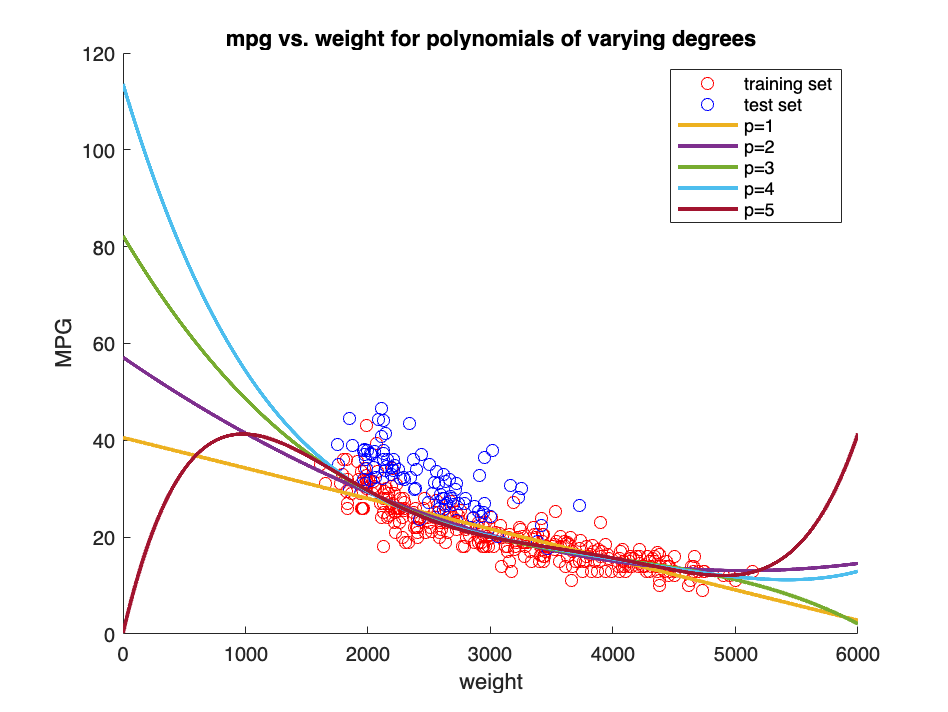


title('mpg vs. weight for polynomials of varying degrees');
xlabel('weight');
ylabel('MPG');
legend('show');

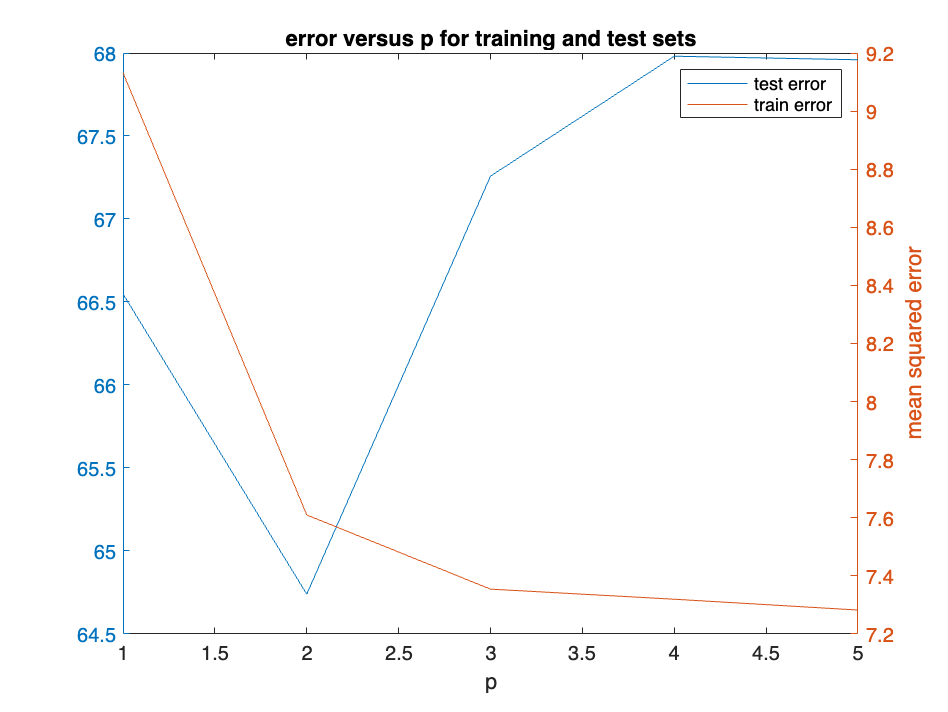


figure;
yyaxis left
plot(p, test_err, 'DisplayName', 'test error');
hold on;
yyaxis right
plot(p, train_err, 'DisplayName', 'train error');
legend('show');
title('error versus p for training and test sets');
xlabel('p');
ylabel('mean squared error');
hold off; 

**(2c) (2 points)** How does the training error change as the order of the polynomial fit is changed? Why does this happen?

fprintf(['The training error decreases only slightly as the order of the \n' ...
    'polynomial increases. This happens because the polynomials coefficients \n' ...
    'were derived from this training data, by minimizing the error, so the \n' ...
    'error is required to be small for all the training data points.'])

The training error decreases only slightly as the order of the 
polynomial increases. This happens because the polynomials coefficients 
were derived from this training data, by minimizing the error, so the 
error is required to be small for all the training data points.

**(2d) (3 points)** How does the test error change as the order of the polynomial fit is changed? For what $p$ is this error minimized? In 1-2 sentences, explain why there are differences between the trends for the test error and for the training error. In particular, compare the test errors to the plot of the fitted polynomials.

fprintf(['The test error decreases a lot from p = 1 to p = 2, and then increases \n' ...
    'to p = 3, after which it increases more slowly to p = 5. The error is minimized \n' ...
    'for p = 2. The error is higher for a larger polynomial order for the test set because\n' ...
    'at this point, the model is overfit. There are differences between the trends for test and train error \n' ...
    'because the polynomial is derived from completely different data that it is tested on, so \n' ...
    'the different error results from the different trend/data points in the test set. Thus, the \n' ...
    'overall error for the training set is much smaller than the test set.'])

The test error decreases a lot from p = 1 to p = 2, and then increases 
to p = 3, after which it increases more slowly to p = 5. The error is minimized 
for p = 2. The error is higher for a larger polynomial order for the test set because
at this point, the model is overfit. There are differences between the trends for test and train error 
because the polynomial is derived from completely different data that it is tested on, so 
the different error results from the different trend/data points in the test set. Thus, the 
overall error for the training set is much smaller than the test set.